## Simulation of Human Vital Sign Signal of a Millimeter Wave Radar

Author : Lin Junyang

Date:     2020.12.10

A simulation of human vital sign signal of a millimeter wave radar.  

A millimeter-wave radar has NonLinear effect on the vital sign signal. This makes it difficult to accurately detect the heartbeat rate.

As a challenge, try develop your algorithm of detecting the heartbeat rate.

% Breath      ●           
%    &       /█\ ----- ┝█ mmWave Radar
% Heartbeat   ∏           

## parameters

clc

include_heartbeat = true;
sig_amp_heartbeat = 0.1;

Breath_PerMinute = 20;   
Heartbeat_PerMinute = 73;   
Breath_Var = 0.2;
Heartbeat_Var = 0.2;  

fs = 50;  %sample rate
SNR = 35;  %dB
NonLinear = true;

sim_cnt = 5;

## Simulation

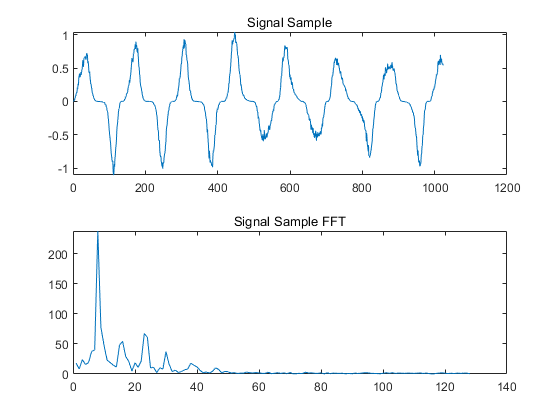


ts = 1/fs;
n = 5000;
T = n/fs;  %simulation time
t = 0:ts:T;
    
for kk=1:sim_cnt
    wb = Breath_PerMinute/60 * 2*pi * (1+2*(rand-0.5)*Breath_Var);   %breath frequency
    wh = Heartbeat_PerMinute/60 * 2*pi * (1+2*(rand-0.5)*Heartbeat_Var);   %breath frequency

    pb = 0.05*(rand(n,1)-0.5); %phase noise of breath signal
    pb2 = 2*pb;
    ph = 0.05*(rand(n,1)-0.5); %phase noise of heartbeat signal
    for k=2:n
        pb(k) = pb(k) + pb(k-1) + wb*ts;
        pb2(k) = pb2(k) + pb2(k-1) + 2*wb*ts;
        ph(k) = ph(k) + ph(k-1) + wh*ts;
    end

    xb = sin(pb);
    if NonLinear
        xb = 0.85*sin(pb) + 0.15 * sin(pb2);
    end
    xh = sig_amp_heartbeat * sin(ph + 2*pi*rand);
    if ~include_heartbeat
        x = xb; %exclude heartbeat signal
    else
        x = xb + xh;
    end
    
    x = awgn(x, SNR);


    %
    if NonLinear
        y = x.^3;
    else
        y = x;
    end

    %plot sim data
    f = abs(fft(y(1:1024)));
    %close
    subplot(211)
    plot(y(1:1024)); title('Signal Sample')
    subplot(212)
    plot(f(1:128)); title('Signal Sample FFT')
    pause(1)
end

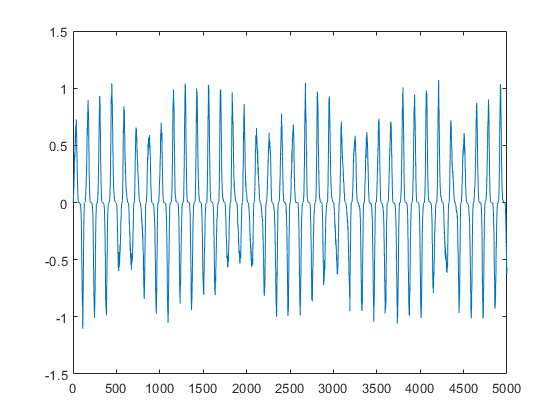

fs =     50


%%
save('vital_sign_sim.mat','y');
figure; plot(y); fs

## Algorithm Development Here: